# 入力の作成方法

% % MPC controller
% % ts探し
tic
% rng(0,'twister');
% ts = 0;
% % 入力のサンプルから評価
% fun = @(p_monte) (p_monte - agent.reference.result.state.p)'*Q_monte*(p_monte - agent.reference.result.state.p); 
% Rmax = 0.269 * 9.81 / 4;  % 乱数の値の範囲
sample = 100;   % サンプル数
horizon = 10;
% 入力 u
% u1 = zeros(sample, 2); % 入力，評価関数の値/ 1horizon, 2h, 3h
% u2 = zeros(sample, 2);
% u3 = zeros(sample, 2);
% u4 = zeros(sample, 2);
% u1 u2 u3 u4 val
% Xdata = zeros(sample , 5);
% ホバリングから±10%の範囲
a = 0.269 * 9.81 / 4 - 0.269 * 9.81 / 4 * 0.1;
b = 0.269 * 9.81 / 4 + 0.269 * 9.81 / 4 * 0.1;
% r = (b-a).*rand(1000,1) + a;
% u1 = (b-a).*rand(horizon, sample) + a
% u1 = repmat((b-a).*rand(sample,1) + a, horizon*4, 1)    % (horizon * sample , 1)
u1 = (b-a).*rand(horizon,sample) + a;
u2 = (b-a).*rand(horizon,sample) + a;
u3 = (b-a).*rand(horizon,sample) + a;
u4 = (b-a).*rand(horizon,sample) + a;
% size(u1)
u1 = repmat(reshape(u1, [1, size(u1)]), 4, 1)

u1 = u1(:,:,1) =

    0.6245    0.6674    0.6563    0.6192    0.7005    0.7245    0.6656    0.6166    0.5943    0.5979
    0.6245    0.6674    0.6563    0.6192    0.7005    0.7245    0.6656    0.6166    0.5943    0.5979
    0.6245    0.6674    0.6563    0.6192    0.7005    0.7245    0.6656    0.6166    0.5943    0.5979
    0.6245    0.6674    0.6563    0.6192    0.7005    0.7245    0.6656    0.6166    0.5943    0.5979


u1(:,:,2) =

    0.6139    0.6523    0.6857    0.6322    0.6979    0.6493    0.6557    0.6114    0.6526    0.6674
    0.6139    0.6523    0.6857    0.6322    0.6979    0.6493    0.6557    0.6114    0.6526    0.6674
    0.6139    0.6523    0.6857    0.6322    0.6979    0.6493    0.6557    0.6114    0.6526    0.6674
    0.6139    0.6523    0.6857    0.6322    0.6979    0.6493    0.6557    0.6114    0.6526    0.6674


u1(:,:,3) =

    0.6168    0.6687    0.6933    0.6467    0.7011    0.6351    0.6638    0.6082    0.6232    0.6636
    0.6168    0.6687    0.6933    0.6467   

% u2 = reshape(u2, [1, size(u2)]);
% u3 = reshape(u3, [1, size(u3)]);
% u4 = reshape(u4, [1, size(u4)]);
% u = reshape(ux, [1, size(ux)]);
% u1 = reshape(4, u1)
% u = [u1; u2; u3; u4]
size(u)   % 4 * horizon * sample

ans =      4    25   100


Adata = zeros(4, horizon, sample)

Adata = Adata(:,:,1) =

     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


Adata(:,:,2) =

     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


Adata(:,:,3) =

     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


Adata(:,:,4) =

     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0 

size(Adata)

ans =      4    10   100



% u1(: ,:) = [(b-a).*rand(sample,1) + a (b-a).*rand(sample,1) + a ];
% u2(: ,:) = [(b-a).*rand(sample,1) + a (b-a).*rand(sample,1) + a ];
% u3(: ,:) = [(b-a).*rand(sample,1) + a (b-a).*rand(sample,1) + a ];
% u4(: ,:) = [(b-a).*rand(sample,1) + a (b-a).*rand(sample,1) + a ];

% 
% Xdata(2, 1:3)
%   % sample * 8 
% % Adata = zeros(sample, 2);
% % 算出
% % Xdata(:, 5) = arrayfun(fun, u1(:), u2(:), u3(:), u4(:));               % 評価関数
% % % Adata(Adata(:, 2)==0, :) = []; % 制約なし
% % [~,min_index] = min(Xdata(:, 2));   % 最小値算出
% % u = Xdata(min_index, 1) % 入力の取得
toc

経過時間は 0.543701 秒です。


sigma = 0.15;
a = 0.269 * 9.81 / 4 - 0.269 * 9.81 / 4 * sigma  

a = 0.5608

b = 0.269 * 9.81 / 4 + 0.269 * 9.81 / 4 * sigma

b = 0.7587


aa = (1-sigma) * 0.269*9.81/4

aa = 0.5608

bb = (1+sigma) * 0.269*9.81/4

bb = 0.7587


A = diag([1 1 1])

A =      1     0     0
     0     1     0
     0     0     1


B= diag([1; 1; 1])

B =      1     0     0
     0     1     0
     0     0     1


% Q_monte = eye(3) * 0.5;
% N = 10;
% p_monte = [randi(N) randi(N) -2]'
% fun = @(p_monte) (p_monte - [10;10;10])'*Q_monte*(p_monte - [10;10;10]); 
% Xdata = fun(p_monte)   
% p_monte_monte = p_monte'

% 
% Fsub = @(z_monte) z_monte > 0
% Fsub(p_monte_monte(:, 3))

## cell配列講座

sample = 5;
P_monte = cell(sample, sample);
% P_monte{1,1} = [2,3,4]
% P_monte{1,1} = 10
% P_monte{2,1} = [2,3,4, 5, 6, 10]
% P_monte{4,2} = [2,54,1,4,56]
b = 10;
a = 0;
for i = 1: sample
    for k = 1:sample
        P_monte{i, k} = ((b-a).*rand(sample,1) + a)'; 
    end
end
P_monte

P_monte = 5×5 の cell 配列
    {[6.9350 2.3513 1.6570 0.6124 5.8568]}    {[2.9126 5.7993 4.9983 6.4983 1.2882]}    {[2.5401 8.7785 9.1627 6.3014 4.3223]}    {[8.0554 2.9692 9.1640 0.5728 0.5035]}    {[4.2336 5.1098 8.7771 0.0252 3.3505]}
    {[1.0211 9.6702 0.3493 6.6205 9.9644]}    {[9.2735 4.5541 4.0973 3.1496 1.8103]}    {[3.5176 7.1723 5.7029 0.5585 5.1208]}    {[7.2697 2.4537 2.5686 6.2826 4.0244]}    {[6.8873 5.2689 8.2838 9.4396 2.8210]}
    {[7.9255 7.3592 9.6447 9.0327 8.8970]}    {[1.2248 6.4155 5.0832 8.5775 2.1554]}    {[2.8074 3.6994 8.8028 3.1118 2.8132]}    {[1.9095 7.1338 2.5604 0.9441 4.7100]}    {[4.8943 4.5677 7.9515 0.0304 5.6055]}
    {[6.1274 8.0869 3.3774 6.4440 4.2942]}    {[3.3179 1.6786 5.3679 6.3000 7.0271]}    {[9.2834 9.9118 4.5169 7.2901 6.7244]}    {[7.6565 1.0143 3.7210 3.9525 3.6856]}    {[6.2843 7.6141 2.4955 9.0876 9.4053]}
    {[7.5984 6.7391 3.0207 9.4092 5.2989]}    {[7.4723 9.5630 1.4903 4.8762 6.5216]}    {[7.2282 4.4865 0.5445 9.6152 9.5403]}    {[

State_1 = P_monte(i, :);
pp = cell2mat(State_1);
State_monte = zeros(sample, 25);

% cell to double
for i = 1:sample
    State_monte(i, 1:sample*sample) = cell2mat(P_monte(i, :));
end

State_monte

State_monte =     6.9350    2.3513    1.6570    0.6124    5.8568    2.9126    5.7993    4.9983    6.4983    1.2882    2.5401    8.7785    9.1627    6.3014    4.3223    8.0554    2.9692    9.1640    0.5728    0.5035    4.2336    5.1098    8.7771    0.0252    3.3505
    1.0211    9.6702    0.3493    6.6205    9.9644    9.2735    4.5541    4.0973    3.1496    1.8103    3.5176    7.1723    5.7029    0.5585    5.1208    7.2697    2.4537    2.5686    6.2826    4.0244    6.8873    5.2689    8.2838    9.4396    2.8210
    7.9255    7.3592    9.6447    9.0327    8.8970    1.2248    6.4155    5.0832    8.5775    2.1554    2.8074    3.6994    8.8028    3.1118    2.8132    1.9095    7.1338    2.5604    0.9441    4.7100    4.8943    4.5677    7.9515    0.0304    5.6055
    6.1274    8.0869    3.3774    6.4440    4.2942    3.3179    1.6786    5.3679    6.3000    7.0271    9.2834    9.9118    4.5169    7.2901    6.7244    7.6565    1.0143    3.7210    3.9525    3.6856    6.2843    7.6141    2.4955   

% pp = cell2mat(P_monte(4, 2))
% pp(2)




% P_monte{2,1}    % 要素を値として取り出す
% P_monte(2,1)    % cell配列として取り出す
% P_monte{4,2} = [2,54,1,4,56]
% 
% P_monte{1,1} = [[1,2,3]; [4,5,6]]
% P = P_monte{1,1,1}
% 
% P = P_monte{4,2}(2:4)

## 乱数の取り方

rng('shuffle')
sigma = 0.3;
delta1 = 0.0; delta2 = 0.0; delta3 = 0.0; delta4 = 0.0;
a = 0.269 * 9.81 / 4 - 0.269 * 9.81 / 4 * sigma;           b = 0.269 * 9.81 / 4 + 0.269 * 9.81 / 4 * sigma;
sample = 10;   % サンプル数
u = (b-a).*rand(sample,4) + a

u =     0.8048    0.5824    0.4665    0.6949
    0.6678    0.5344    0.6757    0.4980
    0.5867    0.6412    0.8265    0.7013
    0.4824    0.8522    0.8006    0.5624
    0.6768    0.6132    0.7381    0.8521
    0.5377    0.7715    0.6444    0.6864
    0.6615    0.5124    0.6164    0.6104
    0.8035    0.8565    0.4726    0.7364
    0.7077    0.4836    0.6086    0.8098
    0.6391    0.5570    0.7006    0.6101


## 重み行列

diag([10.; 10.; 0; 0])

ans =     10     0     0     0
     0    10     0     0
     0     0     0     0
     0     0     0     0



Q_monte_x = 1; Q_monte_y = 1; Q_monte_z = 1000000;
Q_monte = [Q_monte_x 0 0; 0 Q_monte_y 0; 0 0 Q_monte_z]

Q_monte =            1           0           0
           0           1           0
           0           0     1000000


% Q_monte = diag([Q_monte_x, Q_monte_y, Q_monte_z])

Td = 0.1;    % 離散時間幅
Te = 20;	  % シミュレーション時間
x0 = [0.5; 0.; 0; 0; 76];% 初期状態
u0 = [0.; 0.];% 初期状態
ur = [0.;0.];% 目標速度
Xo = [3;1;0;0];  % 障害の位置　(静止障害物)
Particle_num = 1000; % サンプル数
%         sigmav = repmat(0.1, 1,Particle_num); %仮の分散値
%Csigma = 0.001;%　時間ごとに変化する分散値の上昇定数
Csigma = 0.005;%　時間ごとに変化する分散値の上昇定数
Count_sigma = 0;
uxnow =0.05;
uynow =0.05;
umax = 6.5;
remove_flag = 1;
remove_flagI = 1;
% sigma_cnt = 1: Params.H;
sigma_cnt = 2;
sigmax = repmat(0.3+Csigma*(sigma_cnt-1), Particle_num, 1)' %初期時刻

sigmax =     0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050


sigmay = repmat(0.3+Csigma*(sigma_cnt-1), Particle_num, 1)'

sigmay =     0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050


t = 0:0.025:4;
y = (t / 4).^2

y =          0    0.0000    0.0002    0.0004    0.0006    0.0010    0.0014    0.0019    0.0025    0.0032    0.0039    0.0047    0.0056    0.0066    0.0077    0.0088    0.0100    0.0113    0.0127    0.0141    0.0156    0.0172    0.0189    0.0207    0.0225    0.0244    0.0264    0.0285    0.0306    0.0329    0.0352    0.0375    0.0400    0.0425    0.0452    0.0479    0.0506    0.0535    0.0564    0.0594    0.0625    0.0657    0.0689    0.0722    0.0756    0.0791    0.0827    0.0863    0.0900    0.0938


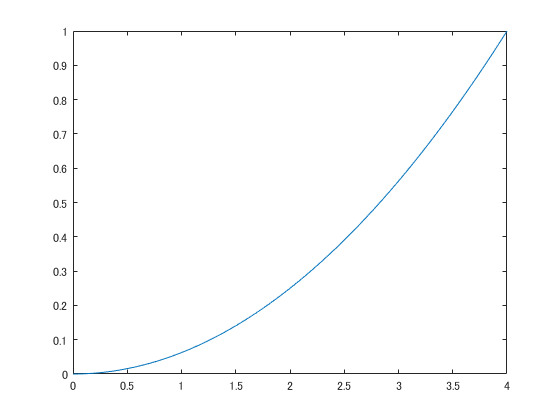

plot(t, y)

sample = 100;
fSubIndex = (1:sample)'

fSubIndex =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


sample = 1000;
H = 5;
sigma = 0.5;              % sigma
ave = 0.269*9.81/4;     % average
y = abs(sigma.*randn(H, sample) + ave)   % 正規分布の乱数

y =     0.3689    0.3802    1.6580    0.2174    1.0479    1.2171    0.7164    0.7331    1.0255    0.4097    1.5817    0.4704    0.2841    1.1612    0.6647    0.1894    1.2308    0.4594    0.8033    0.7770    0.5348    0.5929    0.1361    0.3994    0.2636    0.1494    0.6981    0.3501    0.3871    0.1532    0.9305    0.6068    1.1847    0.5396    0.3834    0.3149    0.7682    0.9982    0.0821    0.6087    0.7679    0.3481    1.5322    0.7902    0.5533    0.6707    1.6986    1.8458    0.6466    1.0311
    0.6718    1.4238    0.7782    0.5041    0.5828    0.8938    0.2335    0.2636    0.2528    0.2767    1.0733    1.2273    1.0143    0.8423    1.8445    0.4111    0.1329    1.0774    0.8967    0.8012    0.1365    0.0577    0.5542    0.3934    0.0359    1.5643    0.8369    0.5772    1.1151    1.0792    0.2775    0.2485    1.2724    0.2613    0.0818    0.5443    1.1887    0.6388    0.4139    1.1867    0.8131    1.2717    0.9611    0.1412    1.0773    0.6200    0.6386    0.3768    0.3001    0


a = [1; 2; 3];
mean(a)

ans = 2